# Exercise 3

## Introduction

Implement a convolutional encoder with the following specifications:


$$\begin{array}{l}
C\left(2,1,2\right)\\
R_c =\frac{1}{2},\\
C_1 =S_1 \oplus S_2 \oplus S_3 ,\\
C_2 =S_1 \oplus S_3 
\end{array}$$


## **a) Convolutional encoder**

Construct a random binary data sequence consisting of 10000 bits. Run the sequence through the convolutional encoder. (*S*1 is the input bit)  

C1 = [1 1 1];
C2 = [1 0 1];
n = 2;
k = 1;
K = 2;
msg = round(rand(1,10000));

G = [poly2oct(C1) poly2oct(C2)]

G =      7     5


conv_trellis = poly2trellis(K+k,G);
spect = distspec(conv_trellis);
dfree = spect.dfree

dfree = 5


encoded_msg = convenc(msg,conv_trellis);

## b) Implement a Viterbi decoder

Implement a Viterbi decoder based on hard decision and test it on the encoded sequence from (a)  

traceback = (K+k)*5;
traceback = traceback+mod(traceback,2);
decoded_msg = vitdec(encoded_msg,conv_trellis,traceback,'trunc','hard');

BitErrorVector=xor(msg,decoded_msg);
BER=sum(BitErrorVector)/length(msg)

BER = 0

## c) Viterbi with random bit errors 

Introduce random bit errors in the encoded bit stream corresponding to BER=10^-4 and check the performance of the Viterbi decoder from (b). Comment on the result

BER = 10^-4;

rx_encoded_msg = bsc(encoded_msg,BER);

BitErrorVector=xor(encoded_msg,rx_encoded_msg);
num_errors =sum(BitErrorVector)

num_errors = 3

BER_encoded=sum(BitErrorVector)/length(encoded_msg)

BER_encoded = 1.5000e-04


decoded_msg = vitdec(rx_encoded_msg,conv_trellis,traceback,'trunc','hard');

BitErrorVector=xor(msg,decoded_msg);
BER_msg=sum(BitErrorVector)/length(msg)

BER_msg = 0

## d) An approximate value for the maximum BER tolerated

Now, assume that errors in the decoded bit stream are unacceptable.

Find an approximate value for the maximum BER tolerated when using the Viterbi decoder from (b). Hint: simple trial varying the BER is indeed a possibility.  

CH_BER(1,:) = 0:10^-3:10^-2;
CH_BER(2,:) = 0:10^-3/10:10^-2/10;
len = length(CH_BER)

len = 11

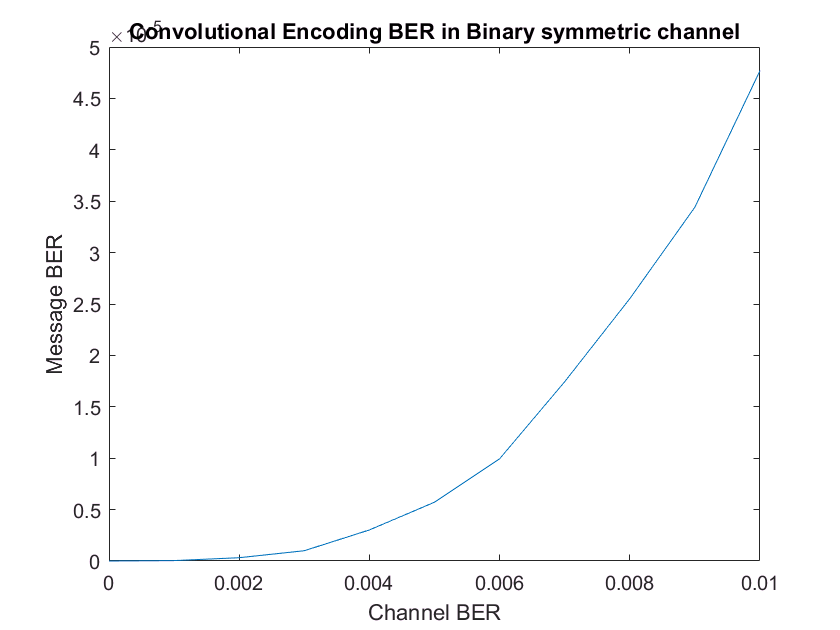

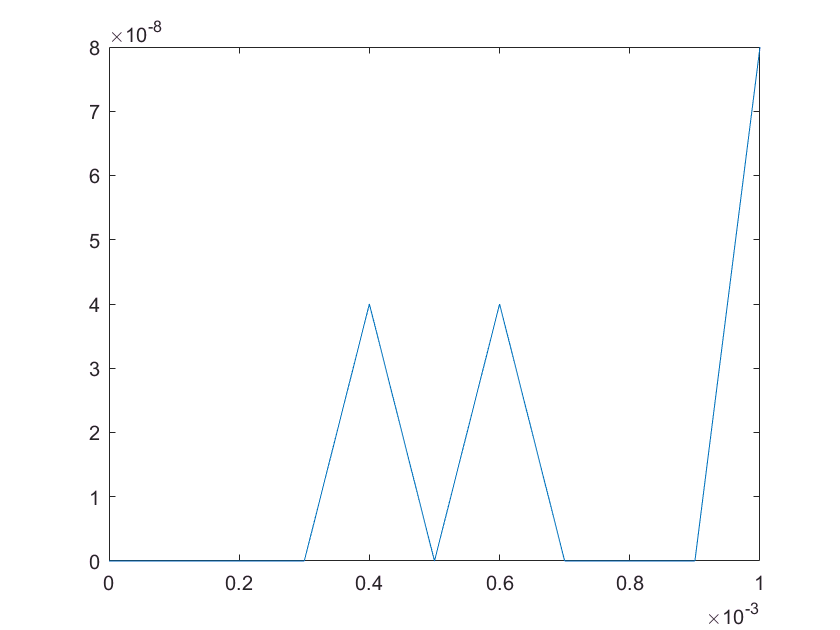

num_sim = 5000;
BER = zeros(1,len);

h = waitbar(0,'0% Simulated...');
for j = 1:len
    SIM_BER_AVG = [0;0];
    for i = 1:num_sim
        rx_encoded_msg(1,:) = bsc(encoded_msg,CH_BER(1,j));
        rx_encoded_msg(2,:) = bsc(encoded_msg,CH_BER(2,j));
        
        decoded_msg(1,:) = vitdec(rx_encoded_msg(1,:),conv_trellis,traceback,'trunc','hard');
        decoded_msg(2,:) = vitdec(rx_encoded_msg(2,:),conv_trellis,traceback,'trunc','hard');
        
        BitErrorVector=xor(msg,decoded_msg(1,:));
        SIM_BER_AVG(1) = SIM_BER_AVG(1) + sum(BitErrorVector)/length(msg) / num_sim;
        BitErrorVector=xor(msg,decoded_msg(2,:));
        SIM_BER_AVG(2) = SIM_BER_AVG(2) + sum(BitErrorVector)/length(msg) / num_sim;
    end
    waitbar(j/len,h,sprintf('%.1f%% Simulated...',j/len*100))
    BER(1,j)=SIM_BER_AVG(1);
    BER(2,j)=SIM_BER_AVG(2);
end
close(h);
figure
plot(CH_BER(1,:),BER(1,:))
xlabel('Channel BER')
ylabel('Message BER')
title('Convolutional Encoding BER in Binary symmetric channel')

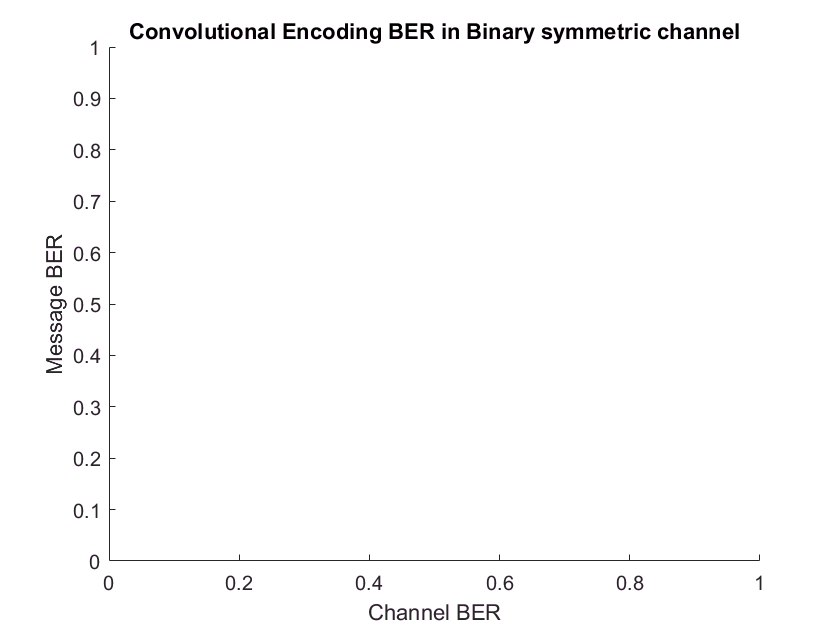

figure
plot(CH_BER(2,:),BER(2,:))
xlabel('Channel BER')
ylabel('Message BER')
title('Convolutional Encoding BER in Binary symmetric channel')